%%% Part C %%%
syms T(t) Kp Ks b To        % Create variables for ode equation
ode = (Kp + Ks)*T + b*diff(T,t) == Ks*To;   % Creating ode equation.
cond = T(0) == 0;           % Initial condition at t = 0
TSol(t) = dsolve(ode, cond) % The dsolve function spits out the response equation. 

$$TSol(t) = \frac{\mathrm{Ks}\,\mathrm{To}-\mathrm{Ks}\,\mathrm{To}\,{\mathrm{e}}^{-\frac{t\,\left(\mathrm{Kp}+\mathrm{Ks}\right)}{b}}}{\mathrm{Kp}+\mathrm{Ks}}$$

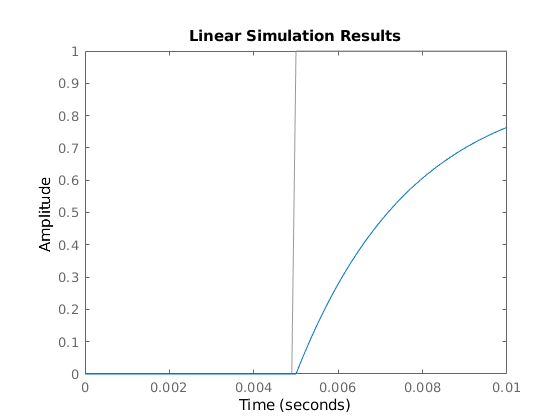



%%% Part D %%%
ks = 100;                   % ks,b, and kp values
b = 0.3;
kp = 10;
sys = tf(ks, [b, ks+kp]);   % Transfer function
t = [0:.1:10]/1000;         % Time array
u = ones(1,numel(t));       % Create an array of ones. This will be a step input.
u(t<.005) = 0;              % Set halve of the values of u array to zero to have step behavior. 
lsim(sys,u,t)               % Run lsim

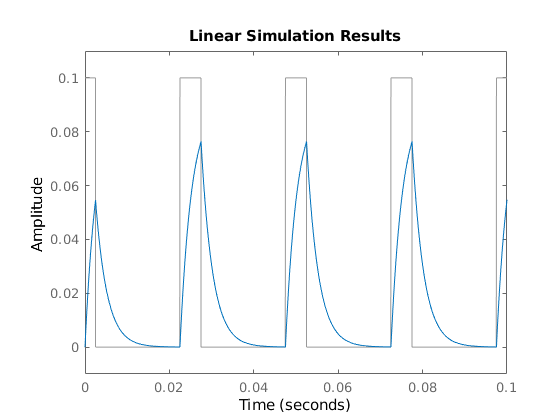



%%% Part E %%%

Fs = 1e5;
t = 0:1/Fs:.5;

hz = 40;
pulsewidth = .005;
pulseperiods = [0:1/hz:.5];

x = pulstran(t,pulseperiods,@rectpuls,pulsewidth)/10;
lsim(sys,x,t)
axis([0 .1 -0.01 0.11])